# Universidade Federal de Campina Grande

# Programa de Pós-Graduação em Engenharia Elétrica

# Estimação e Identificação de Sistemas - 21.2

## Professores: Antonio Marcus Nogueira Lima, Dr.

##                        **Saulo** Oliveira **Dornellas** Luiz, Dr.

## Aluno: Arthur Dimitri Brito Oliveira

## Relatório de Atividade 2 - Modelos Estocásticos

O objetivo deste relatório é caracterizar um modelo linear e invariante no tempo quando adiciona-se uma perturbação desconhecida. 

## Sumário

- Fundamentação Teórica

-     Periodogramas

-     Espectro do sinal

-     Espectro cruzado

- Item 1 

- Item 2

- Item 3   

- Referências

## Fundamentação Teórica

Uma característica comum a sinais de perturbação é que eles não podem ser preditos de forma precisa. No entanto, é possível realizar predições quanto ao valor esperado do seu comportamento futuro. Sendo assim, introduzir elementos estocásticos à descrição do sinal é algo comum. Sendo assim, considrando um sinal uniformemente amostrados, tem-se a forma:

$\begin{array}{rlc}
w(t) + d_1w(t-t)+...+d_nw(t-nT)
&=&c_0e(t) + c-1e(t-T) + ... + c_ne(t-nT)

\end{array}$        (1)

Sendo $e(t) $ e $e(s)$ independentes se $t \neq s$. A distribuição de probabilidade de $e(t)$ tem um grande impacto na forma do sinal $w(t)$. Normalmente, $e(t)$ é uma variável independente, com distribuição normal $e(t) \in N(0,\lambda)$. Sendo assim, $w(t)$ é um sinal contaminado. 

#### Periodogramas

Um periodograma define os conteúdos de frequência de um sinal dentro de um intervalo de tempo finito. Dado um conjunto de entradas  $u(t), \:\: t=1,2,...,N$, $U_N(\omega)$ é dado pela aplicação da DFT ao sinal de entrada:

$U_N(\omega) = \frac{1}{\sqrt{N}} \sum_{t=1}^{N}u(t)e^{-i\omega t}$        (2)

Costumeiramente, considera-se $U_N(\omega)$ para $-\pi \leq \omega \leq \pi$, de modo que a Eq. 2 torna-se:

$u(t) = \frac{1}{\sqrt{N}}\sum_{k=-N/2-1}^{N/2}U_N(2\pi k/N)e^{i2\pi k t/N}$        (3)

Na Eq. 3, o sinal $u(t)$ é uma combinação linear de $e^{i\omega t}$ para diferentes frequências. O termo $U_N(2\pi k/N)$ determina o peso que cada frequência $\omega$ impõe na decomposição do sinal de entrada. 

#### Espectro do Sinal

O conteúdo de frequência de um determinado sinal é determinado pelo que se chama de espectro. A notação utilizada aqui é $\Phi_w(\omega)$. Os periodogramas, como mencionado anteriormente, definem os conteúdos de frequência de um sinal. Essa informação, no entanto, muitas vezes é inacessível devido ao comportamento errático do periodograma como uma função de $\omega$. Busca-se, então, uma definição dentro de um intervalo $t \in [1,\infty)$. Sendo $s(t)$ um sinal quasi-estacionário (média finita e limitada), pode-se calcular a covariância e a covariância cruzada deste sinal:


$$R_s(\tau) = \bar Es(t)s(t-\tau)$$



$$R_{sw}(\tau) = \bar Es(t)w(t-\tau)$$


No caso de sinais quasi-estacionários, o espectro é definido a partir da função de covariância ao aplicar-se a transformada de Fourier:

$\Phi_s(\omega) = \sum_{t=-\infty}^{\infty}R_s(\tau)e^{-i\tau \omega$        (4)

Quando trata-se de dois sinais aleatórios e deseja-se estabelecer a dependencia entre eles, a correlação cruzada entre o sinal de entrada e o sinal é utilizada:

$\Phi_{s\omega}(\omega)=\sum_{t=-\infty}^{\infty}R_{s\omega}(\tau)e^{-i\tau \omega}$        (5)

Um termo mais preciso seria a *densidade espectral, *já que expressa a potência do sinal entre duas frequências $\omega_1$ e $\omega_2$. Assim:


$$\int_{\omega_1}^{\omega_2}\Phi_w(\omega)d\omega$$


Há diversas variações na definição do que é espectro, a depender da natureza do sinal (discreto, contínuo, determinístico, etc). 

#### Espectro Cruzado

Considerando dois sinais $u(t)$ e $y(t)$, é interessante observar como eles variam em conjunto. Analogamente ao espectro, o espectro cruzado entre $u \:\: e \:\: y$ é expresso por:


$$\Phi_{yu} (\omega)$$


Assim, o espectro cruzado é dado pelo produto entre a transformada de Fourier de $y$ e o conjugado da transformada de Fourier de $u$. Diz-se que dois sinais não são correlacionados se $\Phi_{yu}(\omega)=0$.

## Item 1

Sendo o processo $v(t)$ expresso por:

$v(t) = 1.5v(t-1) - 0.7v(t-2) + e(t) + 0.5e(t-1)$        (6)

$e(t)$ é definido como um ruído branco gaussiano. Expressando a Eq. 6 em termos do operador *back-shift* $q
$, tem-se:

$v = 1.5vq - 0.7vq^2 + e + 0.5eq$]


$$v(1-1.5q + 0.7q^2) = e(1+0.5q)$$


$H(q) = \frac{v(q)}{e(q)} = \frac{1+0.5q}{0.7q^2-1.5q+1}$        (7)

Definiu-se o sinal no software MATLAB e obteve-se o  periodograma exibido na Figura 1. 

item_1_process

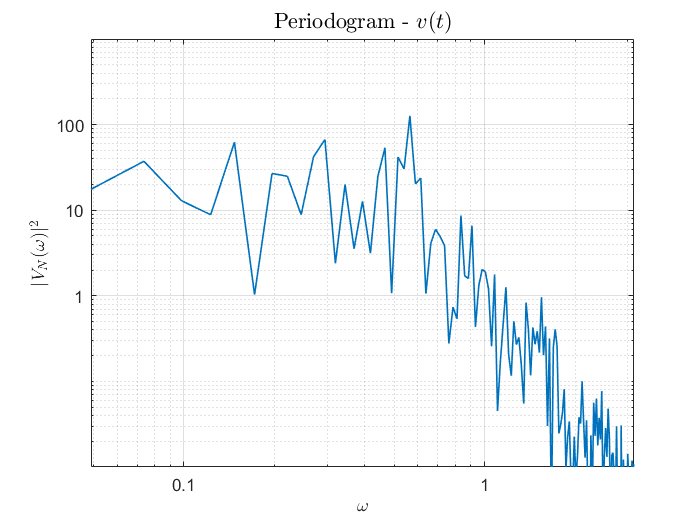

item_1_periodogram_plot

**                                            Figura 1**: Periodograma da realização $v(t)$.

Utilizando a função de transferência de pulso encontrada na Eq. 7, é possível determinar uma versão suavizada das componentes de frequência exibidas no periodograma anterior, isto é, calcular a densidade espectral por meio de: 


$$\Phi_v(w) = \lambda|H(e^{i\omega})|^2$$


O resultado pode ser visualizado na Figura 2. 

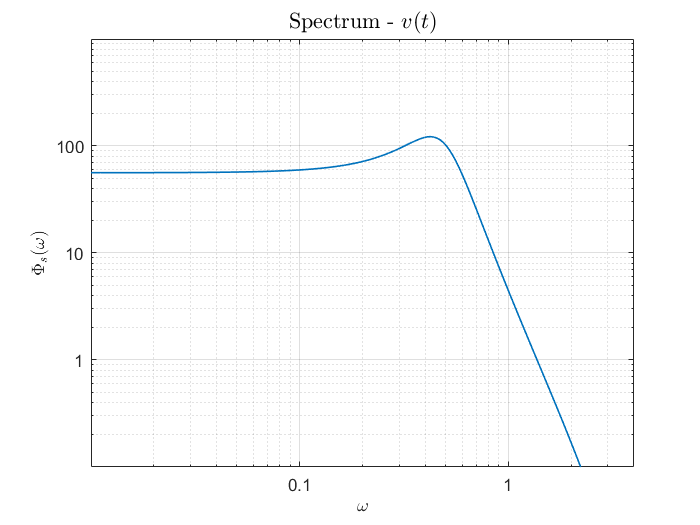

item_1_spectrum_plot

**                                     Figura 2**: Densidade espectral da realização $v(t)$.        

## Item 2

Considere os quatro modelos descritos na Figura 3.

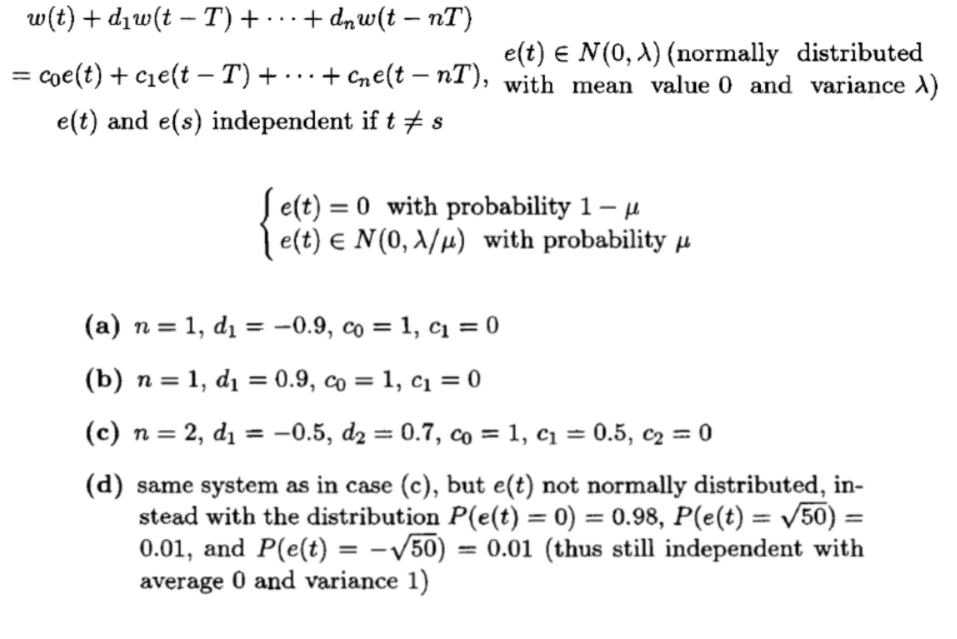

**                            Figura 3**: Modelos estocásticos utilizados. 

Utilizando o software de simulação MATLAB, obteve-se as curvas associadas a cada um dos modelos. Os resultados podem ser observados na Figura 4. Na coluna à esquerda, encontram-se as quatro realizações de $w(t)$. À direita, as covariâncias de cada uma delas.

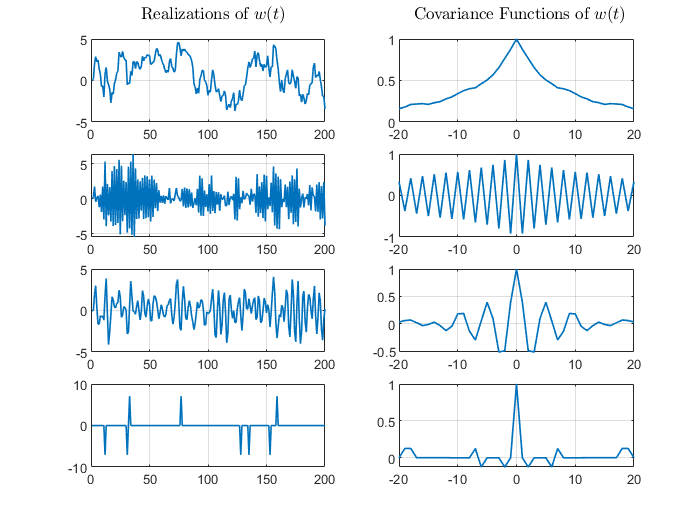

item_2

**                                Figura 4**: Realizações de $w(t)$ e suas covariâncias $R_w(\tau)$

## Item 3

Sendo o processo ARMA conforme expresso na Eq. 8:

$y(t) = -a_1y(t-1) - a_2y(t-2) + e(t) + c_1e(t-1) + c_2e(t-2)$        (8)

Utilizando a forma $y(t) = y_t$ e $e(t)=e_t$, a covariância $R_y(\tau)$, $\tau = 0,1,2$ pode ser obtida ao multiplicar a expressão acima por $y(t), \:\: y(t-1) \:\: e \:\:y(t-2)$ e tomar a esperança matemática. Então:


$$y(t)y(t) = -a_1y(t-1)y(t) - a_2y(t-2)y(t) + e(t)y(t) + c_1e(t-1)y(t) + c_2e(t-2)y(t)$$



$$R_y(0) = E(y_ty_t)=-a_1E(y_{t-1}y_t) - a_2E(y_{t-2}y_t )+ E(e_ty_t) + c_1E(e_{t-1}y_t )+ c_2E(e_{t-2} y_t)$$



$$R_y(1) = E(y_ty_{t-1})=-a_1E(y_{t-1}y_{t-1}) - a_2E(y_{t-2}y_{t-1}) + E(e_ty_{t-1}) + c_1E(e_{t-1}y_{t-1} )+ c_2E(e_{t-2} y_{t-1})$$



$$R_y(2) = E(y_ty_{t-2})=-a_1E(y_{t-1}y_{t-2}) - a_2E(y_{t-2}y_{t-2}) + E(e_ty_{t-2}) + c_1E(e_{t-1}y_{t-2} )+ c_2E(e_{t-2} y_{t-2})$$


No caso da correlação cruzada $R_{ye}(\tau)$, ao multiplicar a Eq. 3 por $e(t), \:\: e(t-1), \:\: e(t-2)$, obtem-se:


$$y(t)e(t) = -a_1y(t-1)e(t) - a_2y(t-2)e(t) + e(t)e(t) + c_1e(t-1)e(t)+ c_2e(t-2)e(t)$$



$$R_{ye}(0) = E(y_te_t)=-a_1E(y_{t-1}e_t) - a_2E(y_{t-2}e_t) + E(e_te_t) + c_1E(e_{t-1}e_t)+ c_2E(e_{t-2} e_t)$$



$$R_{ye}(1) = E(y_te_{t-1})=-a_1E(y_{t-1}e_{t-1}) - a_2E(y_{t-2}e_{t-1}) + E(e_te_{t-1}) + c_1E(e_{t-1}e_{t-1})+ c_2E(e_{t-2} e_{t-1})$$



$$R_{ye}(2) = E(y_te_{t-2})=-a_1E(y_{t-1}e_{t-2}) - a_2E(y_{t-2}e_{t-2}) + E(e_te_{t-2}) + c_1E(e_{t-1}e_{t-2})+ c_2E(e_{t-2} e_{t-2})$$


Sabendo que $e(t) $é um ruído gaussiano, os termos do tipo $E(e_ie_k) = 0$, para quaisquer $i\neq k$. Além disso, $E(e_ie_k) = \lambda$, sempre que $i=k$, já que trata-se de um sinal wgn. Por fim, $E(e_iy_k)=0$ para quaisquer $i>k$. Assim, 


$$R_{ye}(0) = E(y_te_t)= {-a_1E(y_{t-1}e_t) } - a_2E(y_{t-2}e_t) + E(e_te_t) + c_1E(e_{t-1}e_t)+ c_2E(e_{t-2} e_t) = E(e_te_t)$$
 

Utilizando o resultado anterior, e sabendo que $E(e_{t-1}e_{t-1})=E(e_te_t)$


$$R_{ye}(1) = E(y_te_{t-1})=-a_1E(y_{t-1}e_{t-1}) - a_2E(y_{t-2}e_{t-1}) + E(e_te_{t-1}) + c_1E(e_{t-1}e_{t-1})+ c_2E(e_{t-2} e_{t-1}) $$



$$R_{ye}(1) = -a_1E(y_{t-1}e_{t-1}) + c_1E(e_{t-1}e_{t-1}) = -a_1R_{ye}(0)  + c_1E(e_te_t)$$



$$R_{ye}(2) = E(y_te_{t-2})=-a_1E(y_{t-1}e_{t-2}) - a_2E(y_{t-2}e_{t-2}) + E(e_te_{t-2}) + c_1E(e_{t-1}e_{t-2})+ c_2E(e_{t-2} e_{t-2}) $$
 


$$R_{ye}(2) = -a_1E(y_{t-1}e_{t-2})-a_2E(t_{t-2}e_{t-2})+c_2E(e_{t-2}e_{t-2})  = -a_1R_{ye}(1) - a_2R_{ye}(0) + c_2E(e_te_t)$$


No caso das covariâncias $R_y(\tau)$:


$$R_y(0) = E(y_ty_t)=-a_1E(y_{t-1}y_t) - a_2E(y_{t-2}y_t) + E(e_ty_t) + c_1E(e_{t-1}y_t )+ c_2E(e_{t-2} y_t)$$



$$R_y(0) = -a_1R_y(1) - a_2R_y(2) + R_{ey}(0) + c_1R_{ye}(1) + c_2R_{ye}(2)$$



$$R_y(1) = E(y_ty_{t-1})=-a_1E(y_{t-1}y_{t-1}) - a_2E(y_{t-2}y_{t-1} )+ E(e_ty_{t-1}) + c_1E(e_{t-1}y_{t-1} )+ c_2E(e_{t-2} y_{t-1}) $$



$$R_y(1) = -a_1R_y(0) -a_2R_y(1) + c_1R_{ye}(0) + c_2R_{ye}(1)$$



$$R_y(2) = E(y_ty_{t-2})=-a_1E(y_{t-1}y_{t-2}) - a_2E(y_{t-2}y_{t-2}) + E(e_ty_{t-2}) + c_1E(e_{t-1}y_{t-2} )+ c_2E(e_{t-2} y_{t-2}) $$



$$R_y(2) = -a_1R_y(1) -a_2R_y(0)+c_2R_{ye}(0)$$


Para as covariâncias cruzadas:


$$R_{ye}(0) = E(y_te_t) = \lambda$$



$$R_{ye}(1) = -a_1R_{ye}(0)  + c_1E(e_te_t) = \lambda[-a_1+c_1]$$



$$R_{ye}(2) =  -a_1R_{ye}(1) - a_2R_{ye}(0) + c_2E(e_te_t) = -a_1\lambda[-a_1 + c_1] - a_2\lambda + c2\lambda = \lambda[a_1^2- a_1c_1-a_2+ c_2]$$


Para as covariâncias $R_y(\tau)$:


$$R_y(0) =-a_1R_y(1) - a_2R_y(2) + R_{ey}(0) + c_1R_{ye}(1) + c_2R_{ye}(2) $$



$$R_y(0) =  -a_1R_y(1) - a_2R_y(2)  + \lambda + c_1\lambda[-a_1+c_1] + c_2\lambda[a_1^2-a_1c_1 -a_2 + c_2] $$



$$R_y(1) = -a_1R_y(0) -a_2R_y(1) + c_1R_{ye}(0) + c_2R_{ye}(1) = -a_1R_y(0) -a_2R_y(1)  + \lambda[c_1 + c2[-a_1+c_1]]$$



$$R_y(2) = -a_1R_y(1) -a_2R_y(0)+c_2R_{ye}(0) = -a_1R_y(1) -a_2R_y(0) + c_2\lambda$$


Adotando $R_y(0) = \gamma_0$, $R_y(1) = \gamma_1$ e $R_y(2) = \gamma_2$, bem como $\theta_0 = \lambda[1+c1[-a_1+c_1]+c_2\lambda[a_1^2-a_1c_1-a_2+c_2]]$, $\theta_1 = \lambda[c_1 + c2[-a_1+c_1]]$, $\theta_2 = c_2\lambda$, tem-se:

$R_y(0) = \gamma_0 = -a_1\gamma_1 -a_2\gamma_2 + \theta_0$        (9)

$R_y(1) = \gamma_1 = -a_1\gamma_0 -a_2\gamma_1 + \theta_1$        (10)

$R_y(2) = \gamma_2 = -a_1\gamma_1 -a_2\gamma_0 + \theta_2$        (11)

Isolando $\gamma_1$ na Eq. 10, $\gamma_1 = \frac{-a_1\gamma_0 + \theta_1}{a_2+1}$ e substituindo na Eq.11, tem-se:


$$R_y(2) = \gamma_2 =  -a_1\left(  \frac{-a_1\gamma_0 + \theta_1}{a_2+1}\right) - a_2\gamma_0 + \theta_2 = -a_1\left(\frac{-a_1\gamma_0 + \lambda[c_1 + c2(-a_1+c_1)]}{a_2+1}\right) = 
\frac{a_1^2\gamma_0-a_1k_1-a_2\gamma_0+k_2-(a_2)^2\gamma_0+a_2k_2}{(1+a_2)}$$


Substituindo este resultado na Eq. xxx, obtém-se:


$$R_y(0) = \gamma_0 = -a_1\gamma_1 -a_2\gamma_2 + \theta_0 = -a_1\left(\frac{-a_1\gamma_0 + \theta_1}{a_2+1}\right) - a_2\left(\frac{a_1^2\gamma_0-a_1k_1-a_2\gamma_0+k_2-=(a_2)^2\gamma_0+a_2k_2}{(1+a_2)}\right) +...$$
 


$$+ \lambda[1+c1(-a_1+c_1)+c_2\lambda(a_1^2-a_1c_1-a_2+c_2)]$$



$$\gamma_0 = \frac{(a_1)^2\gamma_0-a_1k_1-(a_1)^2a_2\gamma_0+a_1a_2k_1+(a_2)^2\gamma_0-a_2k_2+(a_2)^3\gamma_0-(a_2)^2k_2+k_0+a_2k_0}{(1+a_2)}
$$


Por fim, a variância $\gamma_0$ é expressa por:


$$\gamma_0 = \frac{(1+a_2)\big[1+(c_1)^2+(c_2)^2\big]-2a_1c_1(1+c_2)-2c_2\big[a_2-(a_1)^2+(a_2)^2\big]}{(1-a_2)(1-a_1+a_2)(1+a_1+a_2)}$$


## Referências

[1]   L. LJUNG.** System Identification: Theory for the User **Courier Corporation, 2008. ISBN 0486462781.